## Group Assignment 2 - Image as a function, Image as a matrix, Convolution, etc.

1) You need 2 images. You can take new images or use your previous images. (a suggestion: try to use images where you think you will see something new in different color spaces).

% import images
miranda = imread('../images/IMAGE012.jpg');
computer = imread('../images/IMAGE001.jpg');

### Pixel Processing (Jiayuan)

- Change brightness of your image

- Change contrast of your image

- Change brightness of alternating pixels of the image

### Color Spaces (Miranda)

- Show your images in the different color spaces we discussed. 

- Plot at least 4 different histograms  for each image from the various color spaces (e.g. you can do red,  green, saturation, value). 

- Were these color spaces useful for  your chosen image? Did they show something that you would not see in a  color or grayscale image? Did the histograms show something useful?

### Convolution/linear filtering (Gia)

- Again, use 2 images - these can be same as before or different - your choice

- Apply identity filter to both images, show results

- Apply box filter of 2 different sizes to both images, show results (that would be 4 images). 

- Box filter was a blurring filter. Think about what a sharpening filter would look like and apply it to your 2 images.

- Design a 3x3 Gaussian filter. Apply this to your 2 images.

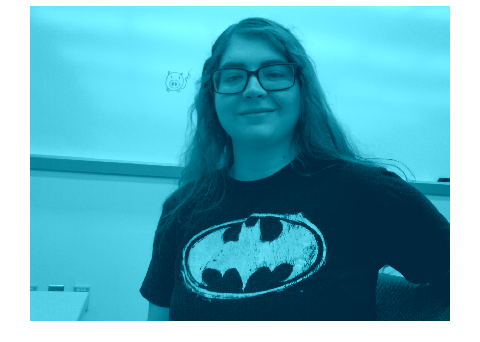

% Identity Filter
I = [0, 0, 0; 0, 1, 0; 0, 0, 0]; % identity filter

miranda_I = imfilter(miranda, I, 'conv');
figure;
imshow(miranda_I);

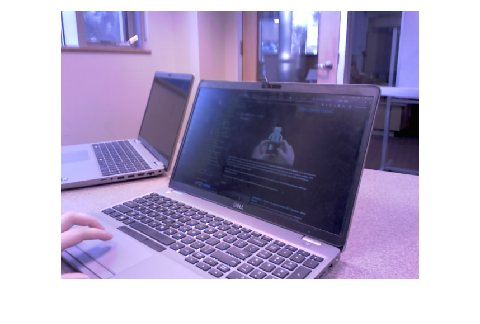


computer_I = imfilter(computer, I, 'conv');
figure;
imshow(computer_I);


% Box Filter
size = 100;
size2 = 25;

B = 1/size^2 * ones(size); 
B2 = 1/size2^2 * ones(size2)

B2 =     0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016
    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016    0.0016  

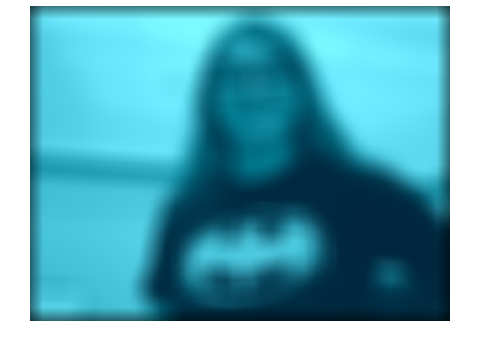


miranda_B = imfilter(miranda, B, 'conv');
figure;
imshow(miranda_B);

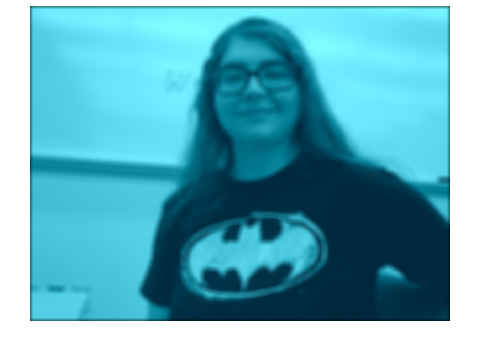


miranda_B2 = imfilter(miranda, B2, 'conv');
figure;
imshow(miranda_B2);

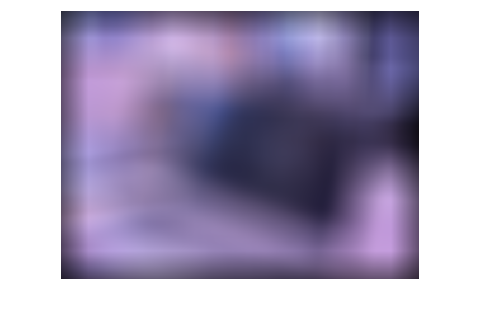


computer_B = imfilter(computer, B, 'conv');
figure;
imshow(computer_B);

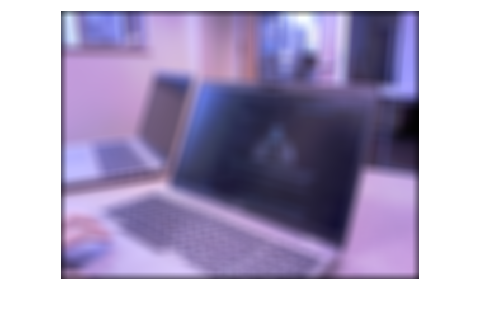


computer_B2 = imfilter(computer, B2, 'conv');
figure;
imshow(computer_B2);

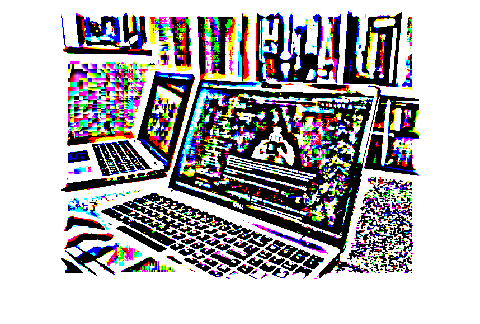


S2 = -1 * ones(size2);
S2(13,13) = 25^2; % why does 2 work, when 1 doesn't?

computer_S2 = imfilter(computer, S2, 'conv');
figure;
imshow(computer_S2);


% even n; what is myopia; what sigma value am I?

% % Gaussian Filter
% std = 30; % miranda myopia
% computer_G = imgaussfilt(computer, std);
% figure;
% imshow(computer);
% figure;
% imshow(computer_G);

Bonus: Bit Plane Extraction

% % conversting to bitplane
% c0 = mod(cd, 2);
% c1 = mod(floor(cd/2), 2);
% c2 = mod(floor(cd/4), 2);
% c3 = mod(floor(cd/8), 2);
% c4 = mod(floor(cd/16), 2);
% c5 = mod(floor(cd/32), 2);
% c6 = mod(floor(cd/64), 2);
% c7 = mod(floor(cd/128), 2);
% 
% % reconstituted image
% cc = 2*(2*(2*(2*(2*(2*(2*c7+c6)+c5)+c4)+c3)+c2)+c1)+c0
